# **RS-HL-13: Multi User Default Code**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/20/24**

### **I. Load the Dataset**

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II. Destination Setting and Time Index Vector Setting

time_index_vector = 100:130;
start_time_index = 100:120;
% 
% destination_1 = 10;
% destination_2 = 12;
% destination_3 = 18;
% destination_4 = 27;
% destination_5 = 40;


number_of_agents = 48;
number_of_destinations = 1;
state_vector = 1:48;


% start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
% destination_values = randsample(state_vector,number_of_destinations);
% destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
% start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));

start_state = 1:48;
destination_values = randsample(state_vector,number_of_destinations);
destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
start_time = 100*ones(1,48);

#### II.1 Run the MDP simulation for each destination

fprintf('Total Number of Destinations: %d\n', number_of_destinations);
for destination_index = 1:number_of_destinations
    fprintf('--------------------------------------\n')
    fprintf('Running MDP %d / %d , Destination %d \n', destination_index,number_of_destinations,destination_values(destination_index));
    MDP.(['MDP', num2str(destination_values(destination_index))]) = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_values(destination_index));

end
    fprintf('--------------------------------------\n')

### III. Configure each Agent's Setting

agents_input = [start_time', start_state', destination_state'];

### IV. Configure the simulation structure setting

% Level 1: Initialize simulation structure
sim = struct();

for time_index = time_index_vector
    sim.(['time' num2str(time_index)]) = {};
end

% Level 2/3: Initialize Agent (Level 2) with States and Destination (Level 3)

number_of_agents = length(agents_input(:,1));

for agent_index = 1:number_of_agents
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('state') = agents_input(agent_index,2);
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('destination') = agents_input(agent_index,3);   
end


### V. Propagation of agents' state

collision_flag = false;

for time_index = time_index_vector

    % If there's no active agent, continue to next time step
    if isempty(sim.(['time' num2str(time_index)]))
       continue;
    end


    % Parse the number of active agents
    number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index)])));

    % Make the status matrix represents current and next
    % [current_state, next_state, destination]
    status_matrix = zeros(3, number_of_active_agents);

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));

    % Find the Next state from Current Agent-State 
    for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');

        % Find the Next state from given MDP pi distribution
        pi_dist = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).('policy_distribution');
        action_number = find(pi_dist(current_state,:) ~= 0);

        if length(action_number) > 1
        action_number = randsample(action_number,1);
        end

        next_state = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
        reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
        state_value =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('state_value');
        action_value  = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('action_value'); 

        % Configure Proposed status matrix for the collision test
        status_matrix(1,active_agent_index) = current_state;
        status_matrix(2,active_agent_index) = next_state;
        status_matrix(3,active_agent_index) = destination;

        % Add State Value
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state_value') = state_value;

        % Save the Original Reward and action value to prepare the update
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_number') = action_number;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_reward') = reward;

        % Add the action number, reward, action value (may be changed)
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;        
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
    end


    % Break when time index reaches the end time
    if time_index == max(time_index_vector)
       break;
    end

    for active_agent_index = 1:number_of_active_agents

        % Don't update the agent already arrived to destination
        if status_matrix(1,active_agent_index) ==  status_matrix(3,active_agent_index)
            continue;
        end

        % Update the time+1 for next state
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = status_matrix(2,active_agent_index);
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('destination') = status_matrix(3,active_agent_index);       
    end
end

### VI. result display

result_matrix = zeros(length(time_index_vector),number_of_agents);
reward_matrix =  zeros(length(time_index_vector),number_of_agents);
state_value_matrix = zeros(length(time_index_vector),number_of_agents);
action_value_matrix = zeros(length(time_index_vector),number_of_agents);
cumulative_reward_matrix = zeros(length(time_index_vector),number_of_agents);

for time_index = time_index_vector

    if isempty(sim.(['time' num2str(time_index)]))
     continue;
    end

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));
    number_of_agents = length(agents_list);

    for agent_index = 1:number_of_agents
        agent_name = cell2mat(agents_list(agent_index));
        agent_no = regexp(agent_name, '\d+','match');
        agent_number = str2double(agent_no{1});

        result_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state');
        reward_matrix(time_index - min(time_index_vector) + 1,agent_number) =  sim.(['time' num2str(time_index)]).(agent_name).('reward');
        state_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state_value');
        action_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('action_value');
        cumulative_reward_matrix(time_index - min(time_index_vector) + 1,agent_number) = sum(reward_matrix(1:time_index - min(time_index_vector) + 1,agent_number));

    end

end

result = [time_index_vector' , result_matrix]

result =    100     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48
   101     2     3     4     5     6     7     8     0     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    48     4    25    26    27    28    31    32    33    34    35    11    11    11    11    38    39    40    41    44    45    46     3     3     4
   102     3     4     5     6     7     8     0     0     0     8     9    10    11    12    13    14    15    16    17    18    19    20    21     4     5     4     3    26    27    32    33    34    11    11    10    10    10    10    11    38    39    40    45    46     3     4     4     5
   103     4     5     6     7     8     0     0     0     0     0     8     9    10    11    12    13    

reward = [time_index_vector', reward_matrix]

reward =    100    -1    -1    -1    -1    -1    -1   100     0   100    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15   -15   -15   -15    -1    -1    -1    -1    -1    -1    -1   -15   -15   -15
   101    -1    -1    -1    -1    -1   100     0     0     0   100    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15    -1   -15   -15    -1    -1    -1    -1    -1   -15   -15    -1    -1    -1    -1   -15    -1    -1    -1    -1    -1   -15    -1    -1    -1
   102    -1    -1    -1    -1   100     0     0     0     0     0   100    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15    -1    -1    -1   -15    -1    -1    -1    -1    -1    -1    -1   -15    -1    -1    -1   -15    -1    -1    -1    -1
   103    -1    -1    -1   100     0     0     0     0     0     0     0   100    -1    -1    -1    -1    

cumulative_reward = [time_index_vector', cumulative_reward_matrix]

cumulative_reward =    100    -1    -1    -1    -1    -1    -1   100     0   100    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15    -1    -1    -1    -1    -1    -1    -1    -1    -1   -15   -15   -15   -15    -1    -1    -1    -1    -1    -1    -1   -15   -15   -15
   101    -2    -2    -2    -2    -2    99   100     0   100    99    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2   -16   -16   -16   -16    -2    -2    -2    -2    -2   -16   -16   -16   -16   -16   -16   -16    -2    -2    -2    -2    -2   -16   -16   -16   -16
   102    -3    -3    -3    -3    98    99     0     0     0    99    98    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3   -17   -17   -17   -17   -17    -3    -3    -3   -17   -17   -17   -17   -17   -17   -17   -17   -17    -3    -3    -3   -17   -17   -17   -17   -17
   103    -4    -4    -4    97    98     0     0     0     0     0    98    97    -4    -4    -

state_value = [time_index_vector', state_value_matrix]

state_value =    100    94    95    96    97    98    99   100     0   100    99    98    97    96    95    94    93    92    91    90    89    88    87    86    81    82    81    80    79    78    79    80    81    82    82    83    83    83    83    82    81    80    79    78    79    80    81    81    82
   101    95    96    97    98    99   100     0     0     0   100    99    98    97    96    95    94    93    92    91    90    89    88    87    82    97    82    81    80    79    80    81    82    83    83    98    98    98    98    83    82    81    80    79    80    81    96    96    97
   102    96    97    98    99   100     0     0     0     0     0   100    99    98    97    96    95    94    93    92    91    90    89    88    97    98    97    96    81    80    81    82    83    98    98    99    99    99    99    98    83    82    81    80    81    96    97    97    98
   103    97    98    99   100     0     0     0     0     0     0     0   100    99    98    97    9

action_value = [time_index_vector', action_value_matrix]

action_value =    100    94    95    96    97    98    99   100     0   100    99    98    97    96    95    94    93    92    91    90    89    88    87    86    81    82    81    80    79    78    79    80    81    82    82    83    83    83    83    82    81    80    79    78    79    80    81    81    82
   101    95    96    97    98    99   100     0     0     0   100    99    98    97    96    95    94    93    92    91    90    89    88    87    82    97    82    81    80    79    80    81    82    83    83    98    98    98    98    83    82    81    80    79    80    81    96    96    97
   102    96    97    98    99   100     0     0     0     0     0   100    99    98    97    96    95    94    93    92    91    90    89    88    97    98    97    96    81    80    81    82    83    98    98    99    99    99    99    98    83    82    81    80    81    96    97    97    98
   103    97    98    99   100     0     0     0     0     0     0     0   100    99    98    97    

### VII. Result Graph

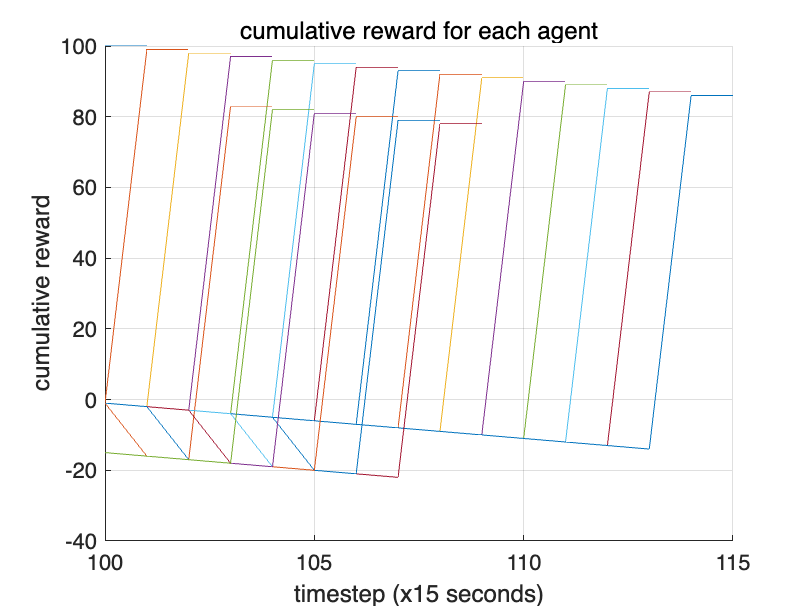

number_of_agents = length(agents_input(:,1));

final_cumulative_reward_vector = zeros(number_of_agents,1);

figure;
hold on
for agent_index = 1:number_of_agents
    cumulative_reward_each_agent = [time_index_vector', cumulative_reward_matrix(:,agent_index)];
    cumulative_reward_each_agent = cumulative_reward_each_agent(cumulative_reward_each_agent(:,2) ~= 0, :);
    plot(cumulative_reward_each_agent(:,1),cumulative_reward_each_agent(:,2))
end
hold off
grid on
title('cumulative reward for each agent')
xlabel('timestep (x15 seconds)')
ylabel('cumulative reward')

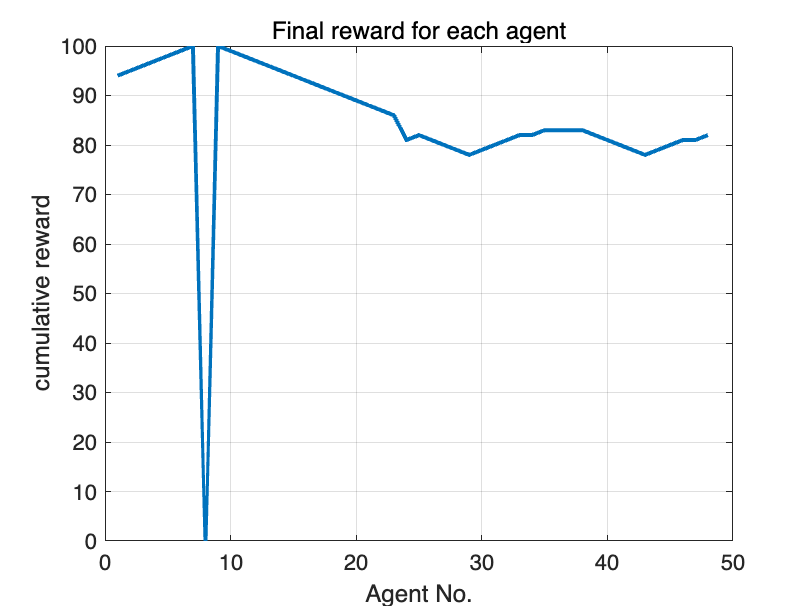


for agent_index = 1:number_of_agents
    each_agent_reward_vector = cumulative_reward_matrix(:,agent_index);
    each_agent_reward= each_agent_reward_vector(each_agent_reward_vector ~= 0);
    if isempty(each_agent_reward) == true
        continue;
    end
    final_cumulative_reward_vector(agent_index) = each_agent_reward(end);
end

figure;
plot((1:number_of_agents)',final_cumulative_reward_vector,"LineWidth",2)
grid on
title('Final reward for each agent')
xlabel('Agent No.')
ylabel('cumulative reward')

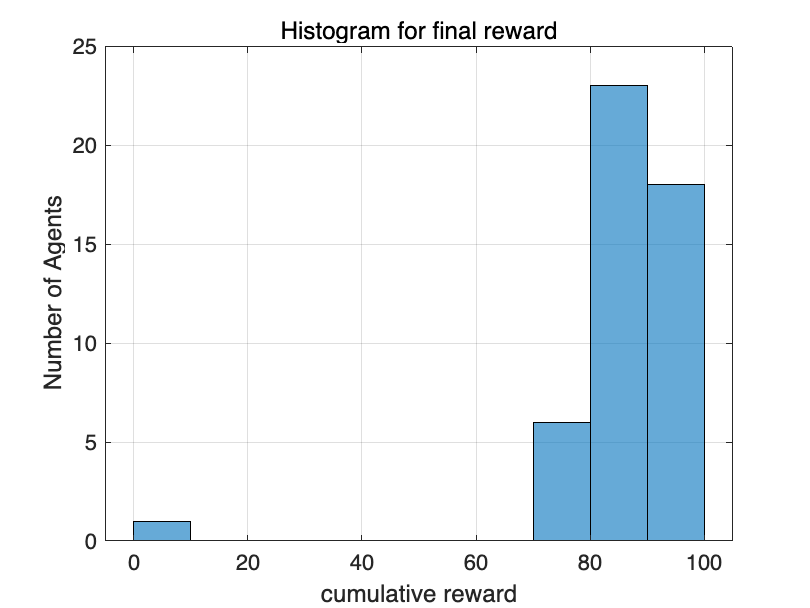


figure;
histogram(final_cumulative_reward_vector)
grid on
title('Histogram for final reward')
xlabel('cumulative reward')
ylabel('Number of Agents')

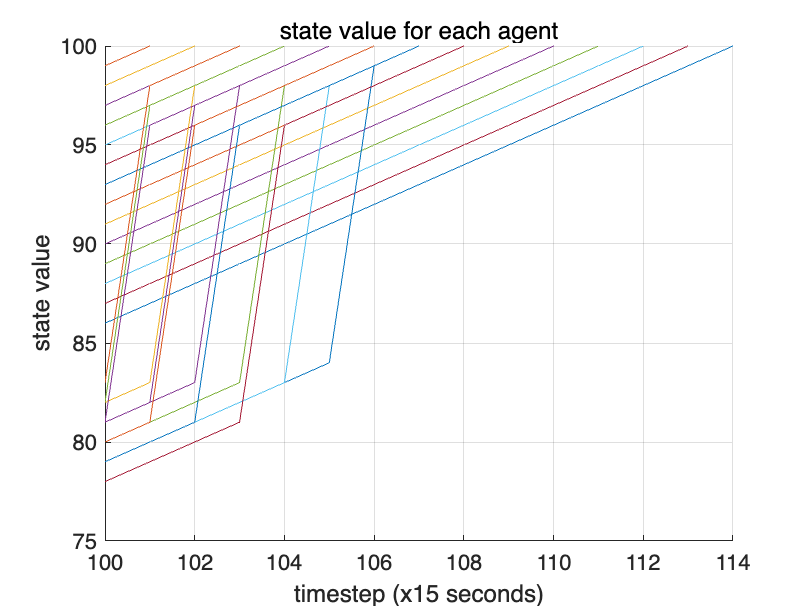



figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2))
end
hold off
grid on
title('state value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('state value')

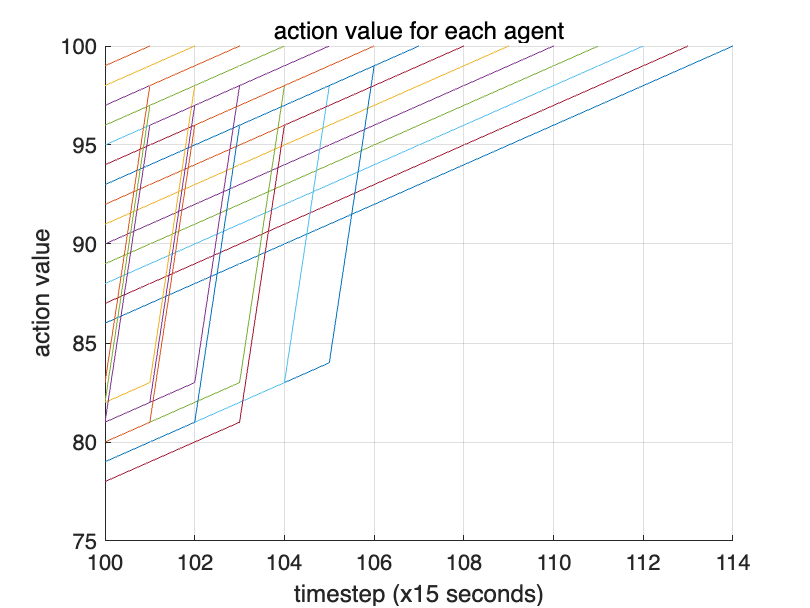


figure;
hold on
for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2))
end
hold off
grid on
title('action value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('action value')

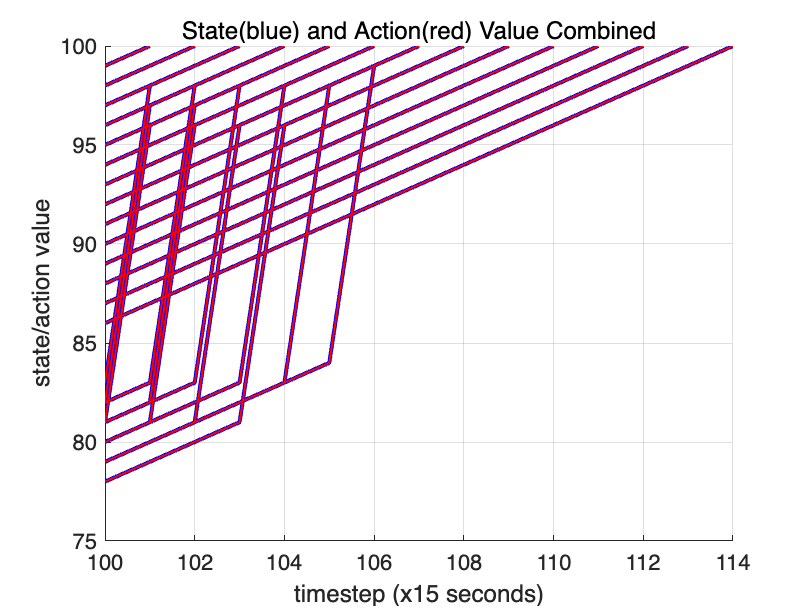




figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2),'b','LineWidth',2)
end


for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2),'r','LineWidth',1)
end
hold off
grid on
title('State(blue) and Action(red) Value Combined')
xlabel('timestep (x15 seconds)')
ylabel('state/action value')

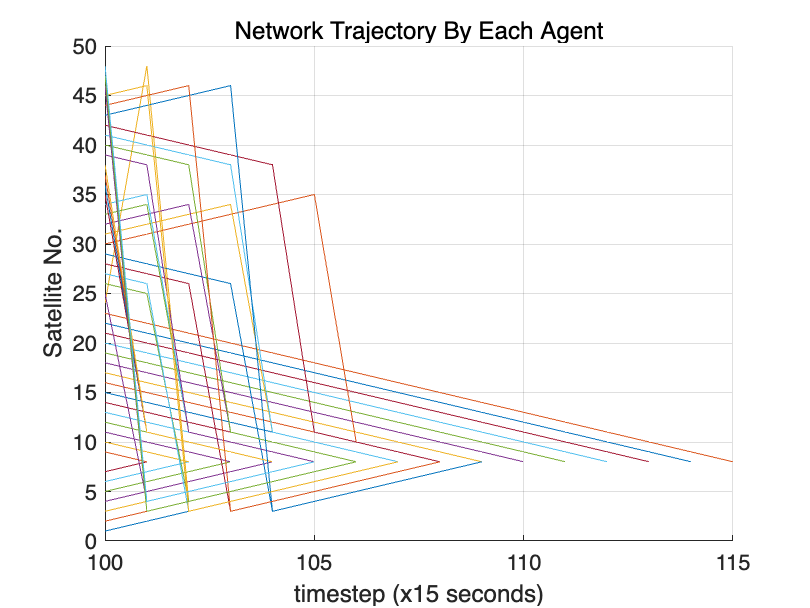



figure;
hold on
for agent_index = 1:number_of_agents
    result_sorted = [result(:,1), result(:,1+agent_index)];
    result_sorted_nonzero = result_sorted(result_sorted(:,2) ~= 0,:);
    plot(result_sorted_nonzero(:,1),result_sorted_nonzero(:,2))
end
hold off
grid on
title('Network Trajectory By Each Agent')
xlabel('timestep (x15 seconds)')
ylabel('Satellite No.')